Program to design FIR Filter for Spectral Compression Algorithm on the UCT SHARC Buoy

Author: Michael Noyce 

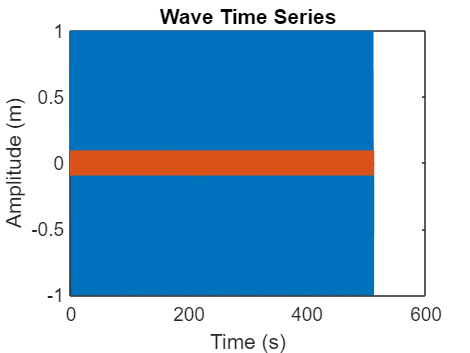

%Inputs for filter 
fs = 100; % highest possible 
freq1 = 0.5;
freq2 = 20; 
t=0:1/fs:512;
wave1 = sin(2*pi*freq1*t);
wave2 = 0.1*sin(2*pi*freq2*t);

waveCombined = wave1 + wave2; 
plot(t, wave1, t, wave2)
xlabel('Time (s)');ylabel('Amplitude (m)');title('Wave Time Series');

Filter Design

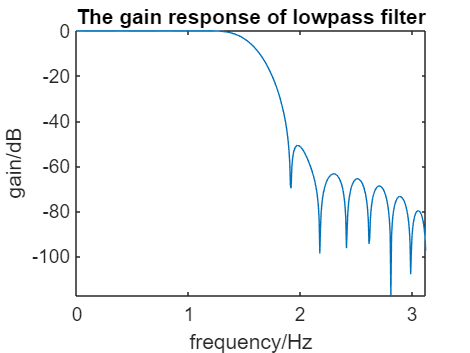

%function to determine impluse response of filter 
n = 32; %length of filter, fir1 requires n-1 
%29 chosen as standard trade off between stm32 processing power and
%accuracy 
fs = 100/16;
fnyquist = fs/2; %2*fmax, or fs/2 
fc = fnyquist/2;  
b = fir1((n-1), fc/fnyquist); %second argument is the normalised cutoff frequency 
% hamming window and lowpass filter used as defaults in fir1

[h,f]=freqz(b,1,512);%amplitude-frequency filter response
figure(1)
plot(f*fs/(2*pi),20*log10(abs(h)))%normalised frequency vs  
xlabel('frequency/Hz');ylabel('gain/dB');title('The gain response of lowpass filter');

Filter Testing 

% Frequency domain before filter 
figure(2)
Y = fft(waveCombined);
L = length(waveCombined)

L = 51201

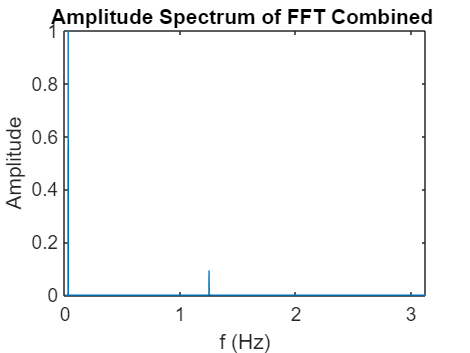

P2 = abs(Y/L);
P1 = P2(1:floor(L/2+1));
P1(2:end-1) = 2*P1(2:end-1);
f = fs*(0:(L/2))/L;
plot(f,P1) 
title('Amplitude Spectrum of FFT Combined ')
xlabel('f (Hz)')
ylabel('Amplitude')

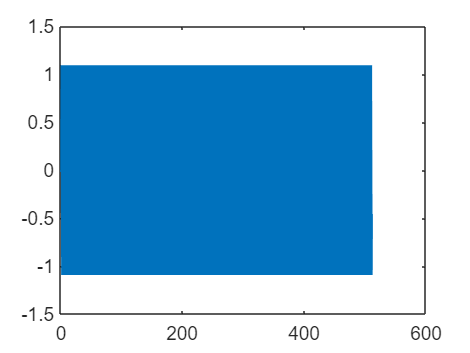


%filter output 
filterOutput = filter(b, 1, waveCombined);
plot(t, filterOutput);


%frequency domain after filter output 
% Frequency domain before filter 
Y = fft(filterOutput);
L = length(filterOutput)

L = 51201

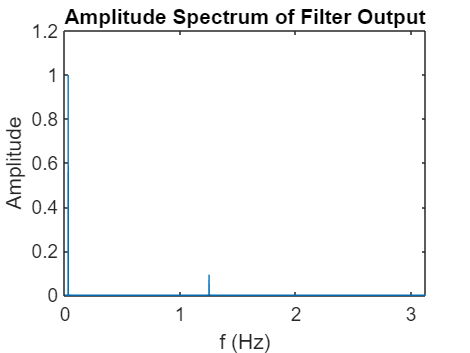

P2 = abs(Y/L);
P1 = P2(1:floor(L/2+1));
P1(2:end-1) = 2*P1(2:end-1);
f = fs*(0:(L/2))/L;
plot(f,P1) 
title('Amplitude Spectrum of Filter Output')
xlabel('f (Hz)')
ylabel('Amplitude')

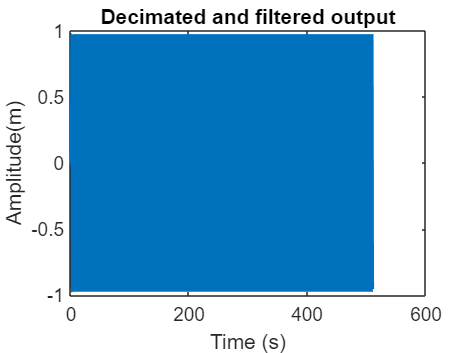


%Decimate 100Hz output to 5 Hz 
decimatedOutput = decimate(filterOutput, 20); 
t_trunc = decimate(t, 20); 
plot(t_trunc, decimatedOutput);
title('Decimated and filtered output'); xlabel('Time (s)'); ylabel('Amplitude(m)')

Convert Data to float32_t fixed point output to use in C

%CMSIS requires filter coefficients to be in reverse time order
b_flip = fliplr(b);

%Convert to float32_t format
str = sprintf([repmat('%.8g,',[1,16]) '\n'],b_flip); %b is the numerator of the FIR filter (which has no denominator)
writematrix(str);